***6-DOF Robotic Arm for Planetary Rover Equipment Station Control***

*Team 23: Shivani Bandirala, Vamsee Krishna Kella, Matthew Nolan, Anup Renikunta*

***Problem Statement:*** This project describes the simulation of a six-degree-of-freedom robotic arm in CAD, as well as workspace analysis and the implementation of various trajectories to perform equipment station control for a planetary rover in the University Rover Challenge.

### **!!!Required ToolBox :Peter Coorke Robotic Toolbox, Matlab Robotics Toolbox!!!**

robot = importrobot('arm_config_547.urdf','DataFormat','row');
viztree = interactiveRigidBodyTree(robot,"MarkerBodyName","link6");

**WorkSpace Analysis**

workspace() %The respective Matlab file : Workspace.m

lim =   -Inf   Inf
     0     0
     0     0
     0     0
     0     0
     0     0


lim =       -Inf       Inf
   -1.5708    1.5708
         0         0
         0         0
         0         0
         0         0


lim =       -Inf       Inf
   -1.5708    1.5708
   -2.3562    2.3562
         0         0
         0         0
         0         0


lim =       -Inf       Inf
   -1.5708    1.5708
   -2.3562    2.3562
   -2.3562    2.3562
         0         0
         0         0


lim =       -Inf       Inf
   -1.5708    1.5708
   -2.3562    2.3562
   -2.3562    2.3562
      -Inf       Inf
         0         0


lim =       -Inf       Inf
   -1.5708    1.5708
   -2.3562    2.3562
   -2.3562    2.3562
      -Inf       Inf
   -2.0944    2.0944


**Joint Space Trajectory- **To provide smooth, continuous motion from one set of joint angles to another, joint-space trajectory creation is used. Run the code below to generate a Joint space trajectory.

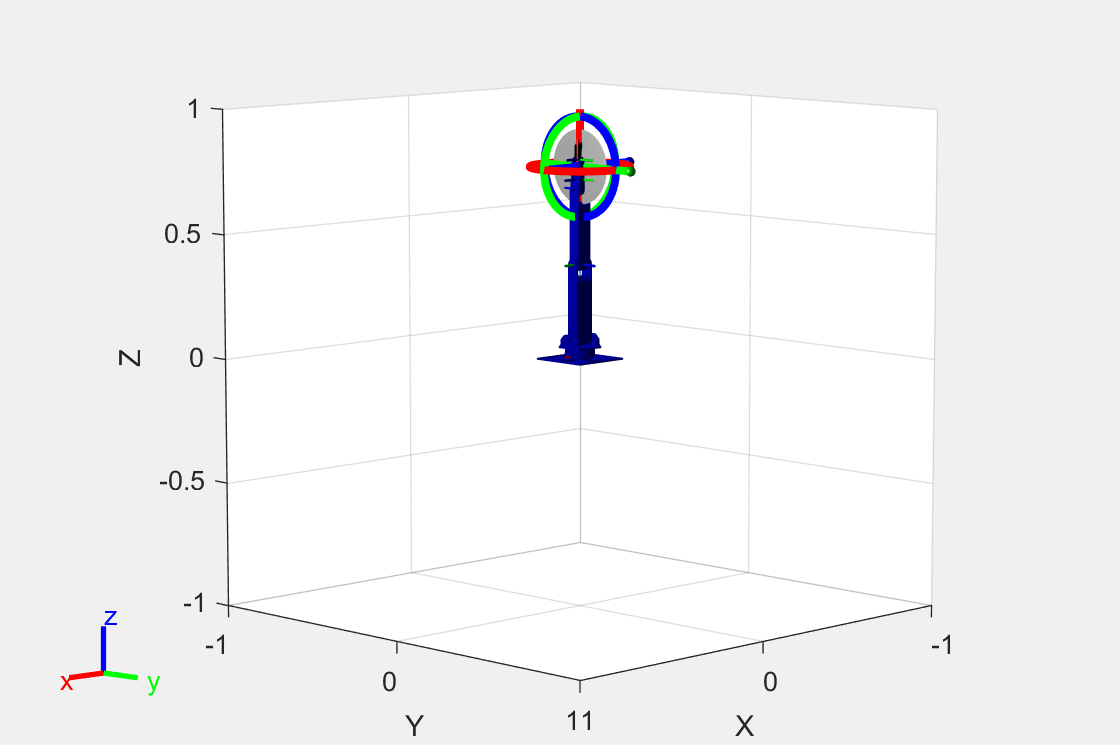

%To generate the Joint Space Trajectory to reach the Switch Box 
switchPose= [0.25,0.1,0.2];
Joint_SpaceTraj(switchPose) %The respective Matlab file :Joint_SpaceTraj.m

**Cartesian Space Trajectory - **All joint angles along the cartesian path are calculated in cartesian trajectory planning. To generate a Cartesian trajectory, the below code is used

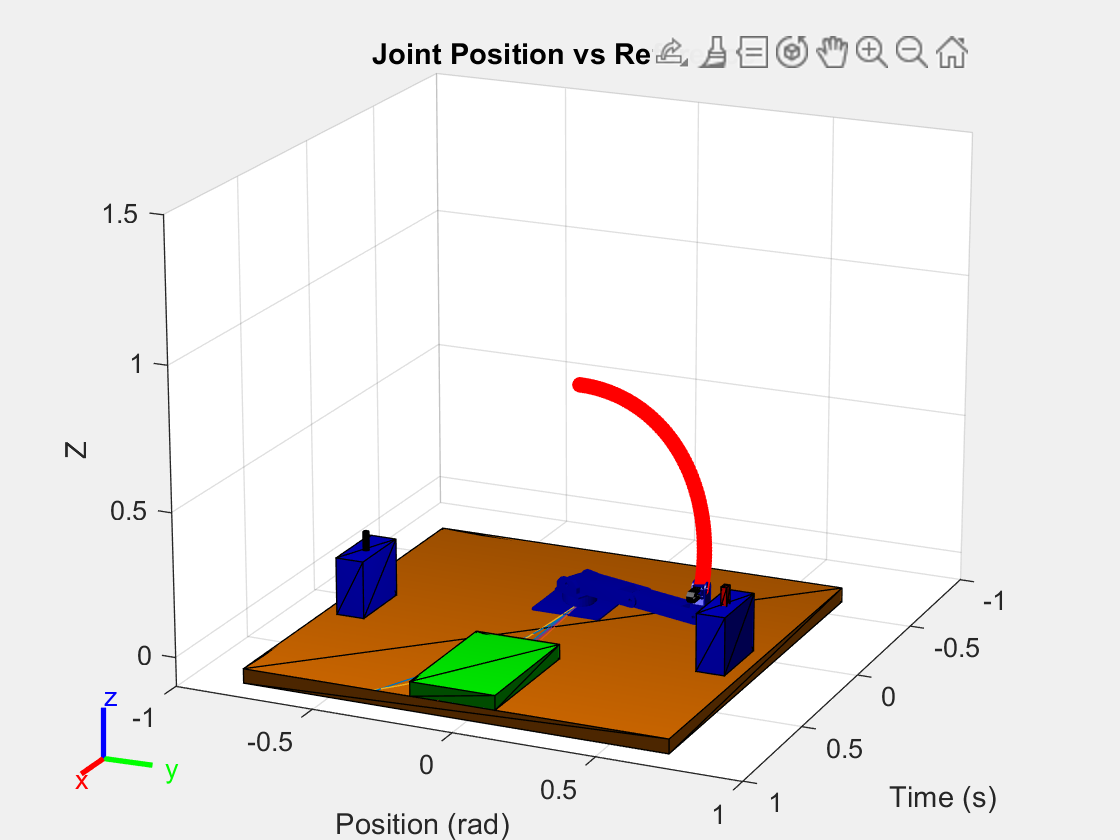

robot1 =   rigidBodyTree with properties:

     NumBodies: 8
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'link1'  'link2'  'link3'  'link4'  'link5'  'link6'  'finger1'  'finger2'}
      BaseName: 'link0'
       Gravity: [0 0 0]
    DataFormat: 'column'


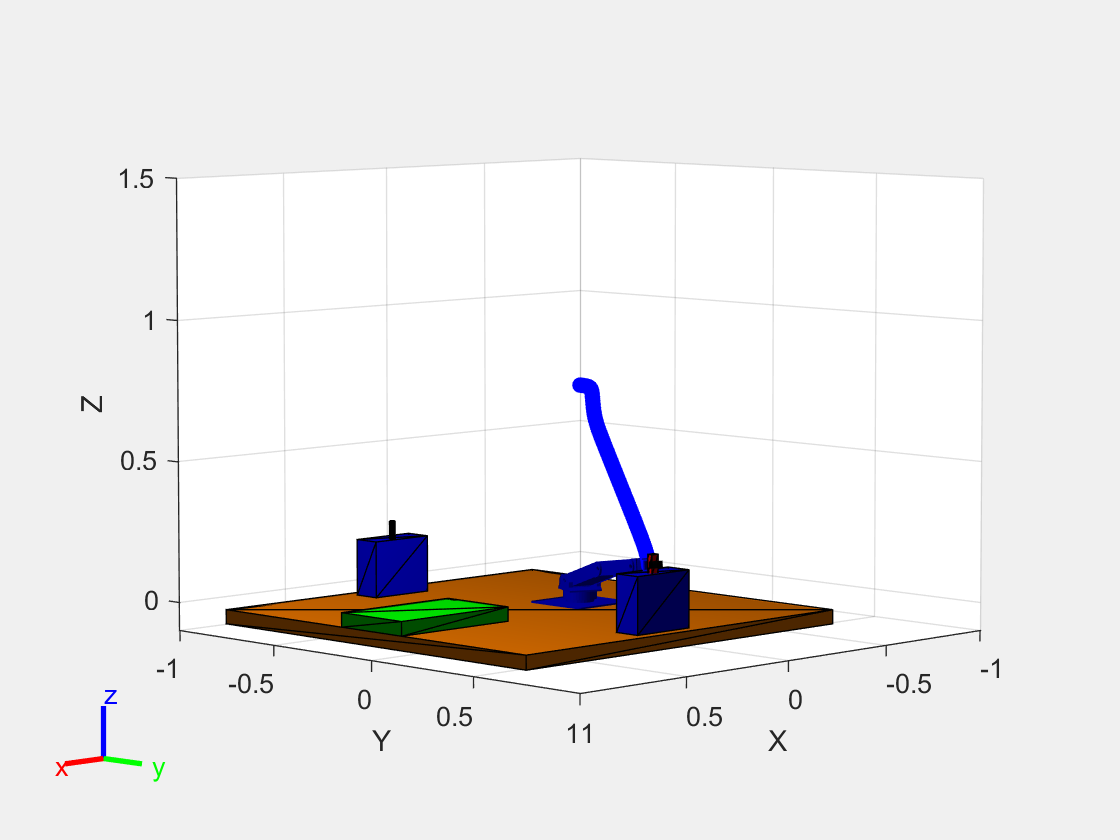

%To generate the Cartesian Space Trajectory to reach the Switch Box 
switchPose= [0.25,0.1,0.2];
Cartesian_SpaceTraj(switchPose) %The respective Matlab file :Cartesian_SpaceTraj.m